clc                     % clear command window
clear                   % clear MATLAB workspace
clf

[robotArduino]= SETUPARDUINO('COM3') 

robotArduino =   arduino with properties:

                  Port: 'COM3'
                 Board: 'Nano33BLE'
         AvailablePins: {'D0-D13', 'A0-A7'}
  AvailableDigitalPins: {'D0-D13', 'A0-A7'}
      AvailablePWMPins: {'D0-D13'}
   AvailableAnalogPins: {'A0-A3', 'A6-A7'}
    AvailableI2CBusIDs: [0, 1]
AvailableSerialPortIDs: [1]
             Libraries: {'I2C', 'Servo'}
Show all properties


steerServo = servo(robotArduino, 'D5', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
driveServo = servo(robotArduino, 'D3', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
panServo = servo(robotArduino, 'D6', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);

writePosition(steerServo, 0.5);      % always start servo-command at 0.5
writePosition(driveServo, 0.3);      % always start servo-command at 0.5
writePosition(panServo, 0.5);        % always start servo-command at 0.5
pause(3.0);                          % wait for Arduino to send stable pwm
warning ('actuators live');

% calibrate to 0.1 - 0.3 - 0.9
writePosition(driveServo, 0.3);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.5);

joy=vrjoystick(1); 
while true
    one = axis(joy, 1)
    two = axis(joy, 2)
    three = axis(joy, 3)
    writePosition(steerServo, -one*0.16 + 0.54)
    writePosition(driveServo, -two*0.02 + 0.35)
    writePosition(panServo, -three*0.5 + 0.5)
    
    pause(0.01)


end

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1016

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.2500

one = 0

two = 0

three = -0.8750

one = 0

two = 0.0138

three = -1

one = 0

two = 0.0138

three = -1

one = 0

two = 0.0138

three = -1

one = 0

two = 0.0138

three = -1

one = 0

two = 0.0138

three = -1

one = 0

two = 0.0138

three = -0.0703

one = 0

two = 0.0138

three = 0.5001

one = 0

two = 0.0138

three = 1

one = 0

two = 0.0138

three = 1

one = 0

two = 0.0138

three = 1

one = 0

two = 0.0138

three = 1

one = 0

two = 0.0138

three = 1

one = 0

two = 0.0138

three = 1

one = 0

two = 0.0138

three = 0.8730

one = -0.0078

two = 0.0138

three = -0.1172

one = 0

two = 0.0138

three = -0.0859

one = 0

two = 0.0138

three = -0.0859

one = 0

two = 0.0138

three = -0.0859

one = 0

two = 0.0138

three = -0.0859

one = 0

two = -0.0742

three = 0

one = 0.0374

two = -0.4531

three = 0

one = 0.1315

two = -0.9453

three = 0

one = 0.1432

two = -1

three = 0

one = 0.1432

two = -1

three = 0

one = 0.1550

two = -1

three = 0

one = 0.1315

two = -1

three = -0.1641

one = 0.0648

two = -0.9531

three = -0.8750

one = -0.1094

two = -0.9727

three = -1

one = -0.1875

two = -0.9609

three = -1

one = -0.4062

two = -0.8672

three = -0.6719

one = -0.6875

two = -0.7656

three = -0.3359

one = -0.9727

two = -0.7656

three = -0.2891

one = -1

two = -0.7656

three = -0.2266

one = -1

two = -0.7656

three = -0.2266

one = -0.6992

two = -0.8281

three = -0.2578

one = -0.1035

two = -0.8672

three = -0.3203

one = 0.5706

two = -0.8437

three = -0.2891

one = 1

two = -0.7812

three = -0.2109

one = 1

two = -0.7031

three = -0.2109

one = 1

two = -0.6641

three = -0.1953

one = 1

two = -0.6641

three = -0.1797

one = 0.9039

two = -0.7266

three = -0.1797

one = -0.5020

two = -0.7656

three = -0.0078

one = -1

two = -0.7480

three = -0.0078

one = -1

two = -0.7598

three = -0.0391

one = -1

two = -0.7656

three = -0.0547

one = -0.1992

two = -0.7422

three = -0.0391

one = 0.9079

two = -0.5801

three = -0.1797

one = 1

two = -0.5469

three = -0.1328

one = 1

two = -0.5469

three = -0.0859

one = 1

two = -0.5469

three = -0.0859

one = 1

two = -0.5469

three = -0.0859

one = 0.9882

two = -0.5469

three = -0.0859

one = 0.7687

two = -0.4062

three = -0.0859

one = -0.0078

two = 0.0256

three = -0.0547

one = 0

two = 0.0374

three = -0.0859

one = 0

two = 0.0374

three = -0.0859

one = 0

two = 0.0256

three = -0.0859

one = 0

two = 0.0256

three = -0.0859

one = 0

two = 0.0374

three = -0.0859

one = 0

two = 0.0374

three = -0.0547

one = 0

two = 0.0138

three = -0.0547

one = 0

two = 0.0374

three = -0.0547

one = 0

two = 0.0256

three = -0.0547

one = 0

two = 0.0138

three = -0.0547

one = 0

two = 0.0374

three = -0.0547

one = 0

two = 0.0374

three = -0.0547

one = 0

two = 0.0197

three = -0.0703

one = 0

two = 0.0315

three = -0.0703

one = 0

two = 0.0138

three = -0.0703

one = 0

two = -0.1035

three = 0

one = 0.1550

two = -0.8691

three = 0

one = 0.3354

two = -1

three = -0.0078

one = 0.3354

two = -1

three = -0.0078

one = 0.3118

two = -1

three = -0.0078

one = 0.2903

two = -1

three = -0.0078

one = 0.1040

two = -0.9336

three = -0.0078

one = -0.0703

two = -0.2305

three = -0.0078

one = -0.0078

two = -0.1016

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

lid = LIDAR('COM6')

lid =   LIDAR with properties:

        lidar: [1×1 serial]
     pol_data: []
    cart_data: []


lidar_data = lid.scan(10000);

lid.close()

gps = NEO_M8U_USB('COM4')

gps =   NEO_M8U_USB with properties:

         DEFAULT_NAME: "USB_NEO_M8U"
    DEFAULT_BAUD_RATE: 9600
    DEFAULT_DATA_TYPE: "uint8"
                  ubx: [1×1 UBX]
               device: [1×1 internal.Serialport]
                 data: []
                 plot: []



gps_data = gps.getBasic();

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

clear gps 

lidar_data = lid.scan(10000);

  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       26632      311770           0           0           0           0           0           0        1235      126995

  Columns 45 through 55

       65555       49171       20499       20499       20499       49171      102419      135187      221204       24596      110648

  Columns 56 through 66

      180224       28717      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

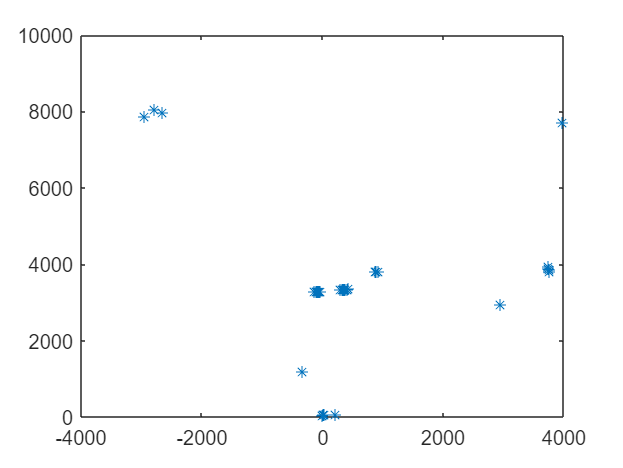

left = lidar_data(:, lidar_data(2,:) > 0 & 0 < lidar_data(1,:) < 500);
plot(left(1,:), left(2,:), '*')

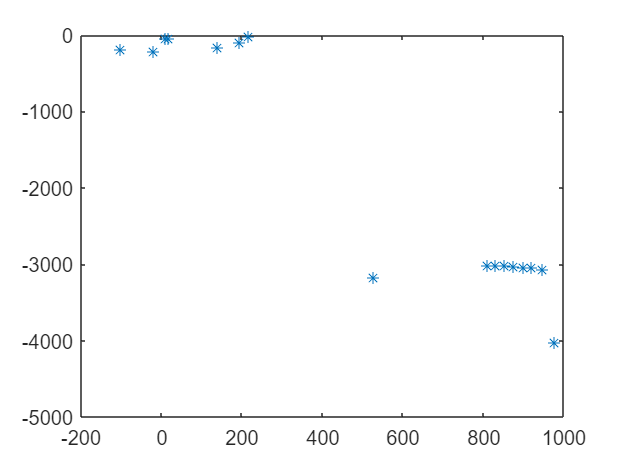

right = lidar_data(:, lidar_data(2,:) < 0 & 0 < lidar_data(1,:) < 500);
plot(right(1,:), right(2,:), '*')

    
lefts = sort(abs(sqrt(left(1,:).^2 + left(2,:).^2)));
rights = sort(abs(sqrt(right(1,:).^2 + right(2,:).^2)));

gpsPlot = figure('Name','Rover Position','NumberTitle','off','Visible','on');
% Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
geolimits([42.29246 42.29418],[-71.26537 -71.26258])
hold on;
% plot rover poition, you can change this line to plot roverX and RoverY 
gpsPoint = geoplot(42.2935, -71.264, 'r*')

gpsPoint =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '*'
         MarkerSize: 6
    MarkerFaceColor: 'none'
       LatitudeData: 42.2935
      LongitudeData: -71.2640
              ZData: [1×0 double]

  Show all properties


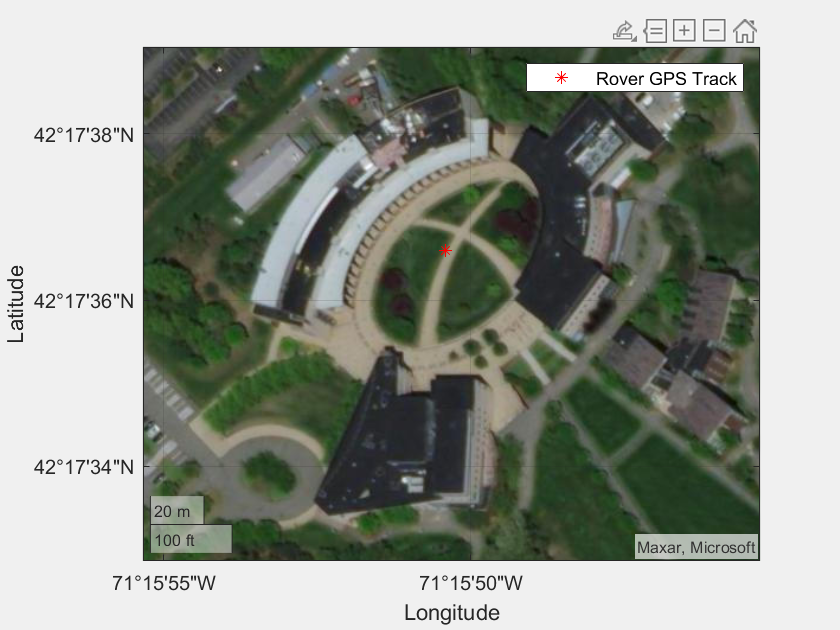

% Import a satellite photo basemap to draw on
geobasemap satellite
legend('Rover GPS Track')

movegui(gpsRoverPlot,'south');

Unrecognized function or variable 'gpsRoverPlot'.

hold off;

plot(lidar_data(1,:), lidar_data(2,:), '*')

Reference to a cleared variable lidar_data.

save('4-27-lg-01', "lidar_data")

  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27784      199898           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      225334      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27801      387290           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      213048      167992

  Columns 56 through 66

      167992      213018      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27804      521178           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      192568      192568

  Columns 56 through 66

      192568      192540      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27807      638426           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      233528      233528

  Columns 56 through 66

      233528      237573      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27810      755930           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      192568      192568

  Columns 56 through 66

      192568      253995      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27813      889818           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      225336      196664

  Columns 56 through 66

      196664      225326      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27816     1023706           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217145       36873      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27818      541658           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      180280      180280

  Columns 56 through 66

      180280      196628      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27821      675546           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0           0       28728      204856

  Columns 56 through 66

      204800          27      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27824      809434           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      208952      167992

  Columns 56 through 66

      167992      208920      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27827      943322           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      213048

  Columns 56 through 66

      213048      217138      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27831       28890           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      217140      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27832      611802           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      196664      192568

  Columns 56 through 66

      192568      196638      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27835      729050           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      208952      192568

  Columns 56 through 66

      192568      192544      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27838      862938           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      200760      192568

  Columns 56 through 66

      192568      200736      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27840      397786           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      225334      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27843      531674           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      200760      200760

  Columns 56 through 66

      200760      213031      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27846      665562           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      172088      172088

  Columns 56 through 66

      172088      184331      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27849      782810           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          57        4152      241720

  Columns 56 through 66

      241721        4122      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27852      916698           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      184376      184376

  Columns 56 through 66

      184376      184340      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27854      451290           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      200760      188472

  Columns 56 through 66

      188472      200734      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27857      585178           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      213048      172088

  Columns 56 through 66

      172088      213020      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27860      719066           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      221240      208952

  Columns 56 through 66

      208952      221234      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27863      819930           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      217140      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27866      953818           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      188472      188472

  Columns 56 through 66

      188472      221216      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27870       39386           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      192568      188472

  Columns 56 through 66

      188472      188441      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27873      173274           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0          21       65556      213012      139284      102420      102420

  Columns 56 through 66

      102420      106527      894244        1320        1322        1328        1329        1329        1329      188436      188436

  Columns 67 through 77

      188416          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27874      756186           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      249876      233492

  Columns 56 through 66

        8211      184344      894189        1261        1271        1281        1283        1286        1286       20500       20500

  Columns 67 through 77

       20500       205

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27877      890074           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0          16       86032       77840       77840       86032      126992      135184      151568      151568

  Columns 56 through 66

      159760      151558      893989        1063        1065        1065        1065        1065        1065      122899      233491

  Columns 67 through 77

      258068       164

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27880     1007322           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      196664      196664

  Columns 56 through 66

      180280      180248      894181        1239        1232        1231        1232        1236        1231       81939       81939

  Columns 67 through 77

       90131       983

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27884       92890           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      200760      200760

  Columns 56 through 66

      200760      204837      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27885      675802           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      184376      184376

  Columns 56 through 66

      184376      229407      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27888      809690           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      180280      180280

  Columns 56 through 66

      180281        4134      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27891      943578           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      254008      217144

  Columns 56 through 66

      217144      253958      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27895       12506           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      176184      167992

  Columns 56 through 66

      167992      167942      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27896      595418           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      204856      192568

  Columns 56 through 66

      192568      204834      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27899      729306           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      155704      151608

  Columns 56 through 66

      151608      151605      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27902      863194           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0       28672           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      229438      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27905      997338           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      184376

  Columns 56 through 66

      184376      217124      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27909       49882           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      163896      163896

  Columns 56 through 66

      163896      217101      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27910      649178           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      167992      167992

  Columns 56 through 66

      167993       61483      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27913      783066           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0          56      229432      213048      213048

  Columns 56 through 66

      212992          52      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27916      916954           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      217140      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27919     1034458           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      180280

  Columns 56 through 66

      180280      217122      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27921      585434           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      163896      163896

  Columns 56 through 66

      163897       12316      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27924      702682           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      184376      184376

  Columns 56 through 66

      184376      213019      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27927      820186           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      155704      155704

  Columns 56 through 66

      155705        8213      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27930      954074           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      176184      176184

  Columns 56 through 66

      176184      225304      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27932      505050           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      196664      196664

  Columns 56 through 66

      196665       16437      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27935      638938           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      196664      196664

  Columns 56 through 66

      196665       41019      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27938      739802           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      163896      163896

  Columns 56 through 66

      163896      200713      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27940      290778           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      172088      172088

  Columns 56 through 66

      172088      208913      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27943      424666           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      208952      208952

  Columns 56 through 66

      208952      213037      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27946      542170           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      208952      208952

  Columns 56 through 66

      208952      241716      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27949      676058           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      225336      172088

  Columns 56 through 66

      172088      225314      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27951      227034           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      172088      172088

  Columns 56 through 66

      172088      217107      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27954      327898           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      180280      180280

  Columns 56 through 66

      180280      204822      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27957      461786           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      213048      213048

  Columns 56 through 66

      213048      249913      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27960      595674           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0          57       53304      188472      188472

  Columns 56 through 66

      188416          56      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27962      146650           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      155704      155704

  Columns 56 through 66

      155705       32795      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27965      247514           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      208952

  Columns 56 through 66

      208952      217136      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27968      381658           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      184376

  Columns 56 through 66

      184376      184348      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27969      980954           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      176184      176184

  Columns 56 through 66

      176184      253983      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27973       50138           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      196664      196664

  Columns 56 through 66

      196664      249901      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27976      184026           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      229431      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27979      301274           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      184376      147512

  Columns 56 through 66

      147512      184322      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27982      435162           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      221240      188472

  Columns 56 through 66

      188472      221224      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27983     1018074           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      208952      208952

  Columns 56 through 66

      208953       49158      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27987      103642           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      180280      180280

  Columns 56 through 66

      180280      221210      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27990      237530           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      167992      167992

  Columns 56 through 66

      167992      229460      893936           0           7           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27993      354778           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      188472      188472

  Columns 56 through 66

      188472      213022      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27994      937690           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      176184      176184

  Columns 56 through 66

      176184      217110      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       27998       23258           0           7           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      241665      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28001      157146           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      159800

  Columns 56 through 66

      159800      217112      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28004      291034           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      184376      184376

  Columns 56 through 66

      184376      208922      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28007      424922           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      208952      208952

  Columns 56 through 66

      208953       16446      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28010      525786           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      200760      200760

  Columns 56 through 66

      200760      249904      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28012       76762           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      237624      237624

  Columns 56 through 66

      237624      237576      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28015      210650           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      176184      176184

  Columns 56 through 66

      176184      213013      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28018      328154           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      221240      200760

  Columns 56 through 66

      200760      221230      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28021      445402           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      204856      200760

  Columns 56 through 66

      200760      204838      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28022     1044698           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      192568      192568

  Columns 56 through 66

      192568      241704      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28026      130266           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      204856      180280

  Columns 56 through 66

      180280      180246      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28029      247770           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      188472      188472

  Columns 56 through 66

      188472      225313      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28032      381914           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      213048      213048

  Columns 56 through 66

      213048      237622      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28035      499162           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      176184      176184

  Columns 56 through 66

      176184      233498      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28037       33754           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      204856      204856

  Columns 56 through 66

      204856      237616      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28040      167642           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      249916      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28043      301530           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      213048      213048

  Columns 56 through 66

      213048      245816      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28046      435418           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      229432      229432

  Columns 56 through 66

      229432      233473      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28047     1018330           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      208952      208952

  Columns 56 through 66

      208952      233522      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28051       87258           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      200760      200760

  Columns 56 through 66

      200760      258098      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28054      221146           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      196664      196664

  Columns 56 through 66

      196664      213028      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28055      804058           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      163896      163896

  Columns 56 through 66

      163897          25      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28058      937946           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      200760      200760

  Columns 56 through 66

      200760      241710      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28062       23514           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      188472      188472

  Columns 56 through 66

      188472      221216      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28065      140762           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      172088      172088

  Columns 56 through 66

      172088      221204      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28066      723674           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      245816      245816

  Columns 56 through 66

      245816      258067      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28069      857562           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      229431      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28072      991450           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      217140      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28074      526042           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      208952      208952

  Columns 56 through 66

      208952      241716      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28077      643290           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      237624      221240

  Columns 56 through 66

      221240      237568      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28080      777178           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      241720      188472

  Columns 56 through 66

      188472      241714      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28082      328410           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      172088      172088

  Columns 56 through 66

      172089       28710      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28085      445658           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      184376      184376

  Columns 56 through 66

      184376      204825      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28088      579546           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      213048      213048

  Columns 56 through 66

      213049        4158      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28091      713434           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217145           0      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28094      830682           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      196664      196664

  Columns 56 through 66

      196664      200737      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28096      382170           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      258104      237624

  Columns 56 through 66

      237624      258066      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28099      499418           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      213048      213048

  Columns 56 through 66

      213049       20482      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28102      633306           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      237624      237624

  Columns 56 through 66

      237624      237576      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28104      167898           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      184376      184376

  Columns 56 through 66

      184376      225310      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28107      285146           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      204856      192568

  Columns 56 through 66

      192568      204834      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28110      419034           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      204856      180280

  Columns 56 through 66

      180280      204828      892928           0           0           0           0           0           0       28672           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28113      552922           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      241720      241720

  Columns 56 through 66

      241721        4115      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28115       87514           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      176184      176184

  Columns 56 through 66

      176184      225304      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28118      221402           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      229431      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28121      338650           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      196664      196664

  Columns 56 through 66

      196664      200737      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28124      472538           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      200760      200760

  Columns 56 through 66

      200760      241710      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28126        7130           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      192568

  Columns 56 through 66

      192568      217128      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28129      141018           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      241720      241720

  Columns 56 through 66

      241720      258064      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28132      274906           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      258110      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28135      392154           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      180280      159800

  Columns 56 through 66

      159800      159745      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28136      975066           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      229432      229432

  Columns 56 through 66

      229433       16397      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28140       60634           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      172088      172088

  Columns 56 through 66

      172032          38      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28143      194522           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      208952      192568

  Columns 56 through 66

      192568      208932      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28144      777434           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      213048      213048

  Columns 56 through 66

      213049        8255      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28147      911322           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      200760      200760

  Columns 56 through 66

      200760      217128      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28150     1028570           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      188472      188472

  Columns 56 through 66

      188472      229410      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28154      114138           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      188472      188472

  Columns 56 through 66

      188472      188440      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28157      231642           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      213048      176184

  Columns 56 through 66

      176184      176149      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28158      830938           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      196664      196664

  Columns 56 through 66

      196665          49      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28161      965082           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      188472      188472

  Columns 56 through 66

      188473       73789      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28165       17626           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0           0          56      245816

  Columns 56 through 66

      245760       28719      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28166      616922           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      208952      208952

  Columns 56 through 66

      208952      245813      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28169      750810           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      188472      188472

  Columns 56 through 66

      188472      258089      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28172      884698           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      167992      167992

  Columns 56 through 66

      167992      167940      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28174      419290           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      151608      151608

  Columns 56 through 66

      151608      237577      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28177      553178           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      200760      200760

  Columns 56 through 66

      200760      204837      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28180      670426           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0          57       36920      176184      176184

  Columns 56 through 66

      176128          43      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28183      787930           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0           0          57       61497

  Columns 56 through 66

       61440       28695      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28185      338906           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      184376      184376

  Columns 56 through 66

      184377       65592      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28188      472794           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      233528      233528

  Columns 56 through 66

      233529       16400      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28191      590298           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          57          56      258104

  Columns 56 through 66

      258105          32      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28194      707546           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0          57       45112      163896      163896

  Columns 56 through 66

      163840          36      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28197      841434           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      204856      204856

  Columns 56 through 66

      204856      237616      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28200      975322           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      213048      213048

  Columns 56 through 66

      213048      217137      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28202      509914           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      184376      184376

  Columns 56 through 66

      184376      229407      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28205      643802           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      192568      192568

  Columns 56 through 66

      192568      225316      892928           0           0           0           0           0           0           0       28672

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28208      761050           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      167992      167992

  Columns 56 through 66

      167993       36901      892928           0           0           0           7           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28211      894938           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      217144      217144

  Columns 56 through 66

      217144      245819      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28213      429530           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      204856      204856

  Columns 56 through 66

      204856      208937      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

straight


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28216      563418           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      221240      221240

  Columns 56 through 66

      221240      237628      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28219      697306           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      229432      176184

  Columns 56 through 66

      176184      229414      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28222      831194           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      159800      147512

  Columns 56 through 66

      147512      159798      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28224      349402           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      213048      192568

  Columns 56 through 66

      192568      192545      892928           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28227      483290           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0           0           0          56      208952      208952

  Columns 56 through 66

      208952      258104      892928           0           0        1679        1677        1677        1676       20505      245785

  Columns 67 through 77

      245785      2457

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28230      617178           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0           0          28      192540      180252      114716      102428

  Columns 56 through 66

       94236       94246      894722        1794        1794        1799        1805        1806        1836           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28233      751066           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0          28      249884      188444      176156      139292      135196

  Columns 56 through 66

      106524       98319      894736        1808        1808        1823        1826        1855           0           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28235      285658           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0           0          28      249884      225308      176156      159772      139292

  Columns 56 through 66

      110620       98335      894740        1812        1812        1826        1828        1889        1958      155678      155678

  Columns 67 through 77

      143390      1065

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28238      402906           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0          29       69661       20508      245788      217116      208924      204828

  Columns 56 through 66

      159772      143384      894752        1824        1824        1843        1853        2045        2075           0           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28241      536794           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0          29      110621       77853       61468      258076      249884      245788

  Columns 56 through 66

      217116      212993      894773        1845        1855        1866        2015        2086        2093      217088           0

  Columns 67 through 77

           0          

left


  Columns 1 through 11

           0           0           0           0           0           0           0      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28244      670682           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0          29      122909       81949       77853       77853       49181       28701

  Columns 56 through 66

       20509        4121      894785        1857        1858        1881        2041        2088        2094      245760           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0          15      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28246      205274           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0          29      155677      147485      102429       90141       49181       16413

  Columns 56 through 66

        4125        4147      894785        1857        1857        1874        2015        2088        2108      249856           0

  Columns 67 through 77

           0          

right


  Columns 1 through 11

           0           0           0           0           0           0          44      892928           0           0           0

  Columns 12 through 22

           0           0           0           0           0           0           0           0           0           0           0

  Columns 23 through 33

           0           0           0           0           0        8410      894420           4       16391        8512       13952

  Columns 34 through 44

        8410       28249      339162           0           0           0           0           0           0           0           0

  Columns 45 through 55

           0           0           0           0          29      163869      135197       94237       53277       53277       40989

  Columns 56 through 66

       36893       24635      894790        1862        1862        1892        2053        2102        2103       49152           0

  Columns 67 through 77

           0          

right


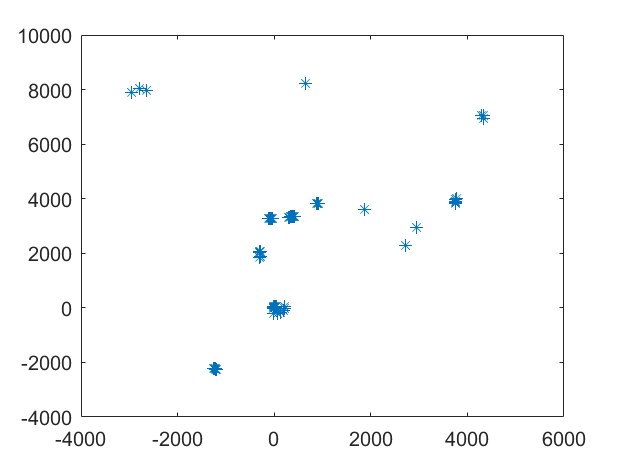

Index exceeds the number of array elements. Index must not exceed 1455.

Error in FunRoboLidarScan (line 29)
    onlyrangedata((64*j)+1:(64*j)+64)=rangedata(1+(66*j):64+(66*j));

Error in LIDAR/scan (line 59)
            [A] = FunRoboLidarScan(obj.lidar);


while true
    lidar_data = lid.scan(10000);
    writePosition(driveServo, 0.38)
    left = lidar_data(:, lidar_data(2,:) > 100 & 0 < lidar_data(1,:) < 500);
    plot(left(1,:), left(2,:), '*')
    right = lidar_data(:, lidar_data(2,:) < -100 & 0 < lidar_data(1,:) < 500);
    plot(right(1,:), right(2,:), '*')
    
    lefts = sort(abs(sqrt(left(1,:).^2 + left(2,:).^2)));
    rights = sort(abs(sqrt(right(1,:).^2 + right(2,:).^2)));
    
    if min(lefts) < 1000 & min(lefts) < min(rights)
        writePosition(steerServo, 1*0.16 + 0.51);
        disp('left')
    elseif min(rights) < 1000 & min(rights) < min(lefts)
        writePosition(steerServo, -1*0.16 + 0.51);
        disp('right')
    else
        writePosition(steerServo, 0.51);
        disp('straight')
    end
    plot(lidar_data(1,:), lidar_data(2,:), '*')
    pause(0.1)
end

writePosition(driveServo, 0.35);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.51);

gpsPlot = figure('Name','Rover Position','NumberTitle','off','Visible','on');
% Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
geolimits([42.29246 42.29418],[-71.26537 -71.26258])
hold on;
% plot rover poition, you can change this line to plot roverX and RoverY 
gpsPoint = geoplot(42.2935, -71.264, 'r*')
% Import a satellite photo basemap to draw on
geobasemap satellite
legend('Rover GPS Track')
movegui(gpsRoverPlot,'south');

function [robotArduino]= SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot test 
% controller. It requires which COM port your Arduino is attached to 
% as its input and returns an Arduino object called robotArduino
% D. Barrett 2022 Rev2
% Create a arduino object so that it can be used in functions
% a = arduino('setToYourComNumber','Uno','Libraries','Servo');
   robotArduino = arduino(COMPORT,'Nano33BLE',"Libraries",{'Servo','I2C'});
end

function wave, waypoints = gpsWaypoint(gps_data, waypoints)
    [dist, angle] = distance(gps_data.latitude, gps_data.longitude, wlat, wlon);
    if dist < cutoff
        waypoints(0) = [];
    end
    delta = angdiff(gps_data.heading, angle);
    if delta > pi/2
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 0 0 0 1 2]);
    elseif delta > 0
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 0 1 2 0 0]);
    elseif delta < -pi/2
        wave = spline([-3 -2 -1 0 1 2 3], [2 1 0 0 0 0 0]);
    else
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 2 1 0 0 0]);
    end
end

function wave = lidarWallFollow(lidar_data)
    left = lidar
end